clear;
clc;
set(0,'defaulttextinterpreter','latex');

% Time increment and movement steps
time_increment = 60/110 * 1000; % converting to milliseconds
steps_left = 12;
steps_up = 7;
steps_right = 12;
steps_down = 7;
movement_distance = 0.7;

% Define the corners of the ground truth rectangle
x_true = [0, 8.4, 8.4, 0, 0];
y_true = [1.25, 1.25, 6.15, 6.15, 1.25];

figure;
idx = 1;
subplot_idx_raw = 1;
subplot_idx_filt = 2;

Colours = [
    0 0 1;
    0 1 0;
    1 0 1;
    0.34, 0.70, 0.91;
    0, 0.62, 0.45;
    0.80, 0.47, 0.65
    ];

% Loop through each file
for fileNum = 1:6
    % Construct the filename
    filename = sprintf('PDR_FC112_Final%d.txt', fileNum);
    
    % Initialise arrays to hold the x, y, and t data
    x = [];
    y = [];
    t = [];
    
    % Open the file for reading
    fid = fopen(filename, 'r');
    
    % Read the file line by line
    while ~feof(fid)
        line = fgetl(fid);
        if line == -1
            break;
        end
        % Use regular expressions to extract the x, y, and t values
        matches = regexp(line, 'x = (?<x>-?\d+\.\d+), y = (?<y>-?\d+\.\d+), t = (?<t>\d+)', 'names');
        if ~isempty(matches)
            x = [x; str2double(matches.x)]; %#ok<*AGROW> 
            y = [y; str2double(matches.y)];
            t = [t; str2double(matches.t)];
        end
    end
    
    % Close the file
    fclose(fid);
    
    % Generate the path taken
    path_x = [8.4];
    path_y = [1.25];
    path_t = [0; t(2)];
    for i = 1:(1000*1000/time_increment)
        if mod(i-1, steps_left + steps_up + steps_right + steps_down) < steps_left
            path_x(end+1, 1) = path_x(end) - movement_distance;
            path_y(end+1, 1) = path_y(end);
        elseif mod(i-1, steps_left + steps_up + steps_right + steps_down) < (steps_left + steps_up)
            path_x(end+1, 1) = path_x(end);
            path_y(end+1, 1) = path_y(end) + movement_distance;
        elseif mod(i-1, steps_left + steps_up + steps_right + steps_down) < (steps_left + steps_up + steps_right)
            path_x(end+1, 1) = path_x(end) + movement_distance;
            path_y(end+1, 1) = path_y(end);
        else
            path_x(end+1, 1) = path_x(end);
            path_y(end+1, 1) = path_y(end) - movement_distance;
        end
        path_t(end+1, 1) = path_t(end) + time_increment;
    end
    
    % Initialise error arrays
    error_x = [];
    error_y = [];
    error_t = [];
    total_error = [];
    
    % Find the matching time points and compute the errors
    for i = 1:length(t)
        [~, closestIndex] = min(abs(path_t - t(i)));
        if abs(path_t(closestIndex) - t(i)) <= 500 % time difference in milliseconds
            error_x(end+1, 1) = path_x(closestIndex) - x(i);
            error_y(end+1, 1) = path_y(closestIndex) - y(i);
            error_t(end+1, 1) = path_t(closestIndex) - t(i);
        end
    end

    for i = 1:length(error_x)
        total_error(i, 1) = sqrt(error_x(i).^2 + error_y(i).^2);
    end
    
    % Plot the data and errors for this file
    if fileNum < 4
        subplot(3, 2, subplot_idx_raw)
        plot(x, y, '-', 'LineWidth', 1.5, 'Color', Colours(fileNum, :));
        hold on;
        plot(x_true, y_true, 'k-', 'LineWidth', 1.5);
        legend('PDR Path', 'Ground Truth', 'Interpreter', 'latex');
        title(sprintf('Pedestrian Dead Reckoning - Test %d', fileNum));
        subplot_idx_raw = subplot_idx_raw + 2;
    end
    if fileNum > 3
        subplot(3, 2, subplot_idx_filt)
        plot(x, y, '-', 'LineWidth', 1.5, 'Color', Colours(fileNum, :));
        hold on;
        plot(x_true, y_true, 'k-', 'LineWidth', 1.5);
        legend('PDR Path', 'Ground Truth', 'Interpreter', 'latex');
        title(sprintf('Pedestrian Dead Reckoning - Test %d', fileNum));
        subplot_idx_filt = subplot_idx_filt + 2;
    end
    xlabel('$x$ [m]');
    ylabel('$y$ [m]');
    grid on;
    hold off;
    
    % Display the error for this file
    fprintf('Test %d errors:\n', fileNum);

    disp('Mean total error:')
    disp(mean(total_error))
    disp('STD total error:')
    disp(std(total_error))
    disp('Minimum total error:')
    disp(min(total_error))
    disp('Maximum total error:')
    disp(max(total_error))
    disp('Range')
    disp(range(total_error))
    disp('Quartiles Total Error:')
    disp(quantile(total_error, [0.25 0.5 0.75 0.9]))
    disp('IQR:')
    disp(iqr(total_error))
end

Test 1 errors:


Mean total error:


    5.6951



STD total error:


    2.3204



Minimum total error:


    0.7058



Maximum total error:


   10.4646



Range


    9.7588



Quartiles Total Error:


    4.0744    5.6152    7.4625    8.8306



IQR:


    3.3881



Test 2 errors:


Mean total error:


    5.3758



STD total error:


    2.2626



Minimum total error:


    0.0234



Maximum total error:


   10.2320



Range


   10.2085



Quartiles Total Error:


    3.7247    5.4435    6.9089    8.6572



IQR:


    3.1842



Test 3 errors:


Mean total error:


    4.8101



STD total error:


    2.1881



Minimum total error:


    0.4910



Maximum total error:


    9.0523



Range


    8.5614



Quartiles Total Error:


    3.3407    4.7507    6.4335    8.0256



IQR:


    3.0928



Test 4 errors:


Mean total error:


    4.9095



STD total error:


    2.3197



Minimum total error:


    0.3616



Maximum total error:


    9.8863



Range


    9.5247



Quartiles Total Error:


    3.1223    5.0570    6.4693    8.0479



IQR:


    3.3469



Test 5 errors:


Mean total error:


    4.5395



STD total error:


    2.5020



Minimum total error:


    0.1874



Maximum total error:


   10.8189



Range


   10.6315



Quartiles Total Error:


    2.4453    4.6154    5.8766    8.1223



IQR:


    3.4312



Test 6 errors:


Mean total error:


    4.8704



STD total error:


    2.1755



Minimum total error:


    0.1205



Maximum total error:


    9.9107



Range


    9.7902



Quartiles Total Error:


    3.0023    4.8616    6.3841    7.8817



IQR:


    3.3817



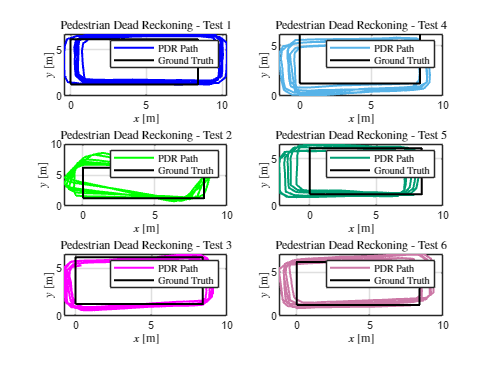


% Set the figure size
fig = gcf;
fig.PaperUnits = 'centimeters';
fig.PaperPosition = [0 0 20 27]; % This will stretch the plot across an width = 21cm, height = 29.7cm
fig.PaperSize = [20 27];

% Save the figure with the specified resolution
print(fig, 'PDR_Plots', '-depsc', '-r600'); % '-depsc' is used for EPS color

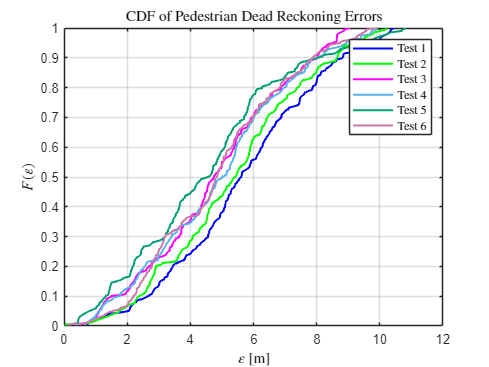

clear;
clc;
set(0,'defaulttextinterpreter','latex', 'DefaultLegendInterpreter', 'latex');

% Time increment and movement steps
time_increment = 60/110 * 1000; % converting to milliseconds
steps_left = 12;
steps_up = 7;
steps_right = 12;
steps_down = 7;
movement_distance = 0.7;

figure;
idx = 1;
subplot_idx_raw = 1;
subplot_idx_filt = 2;

Colours = [
    0 0 1;
    0 1 0;
    1 0 1;
    0.34, 0.70, 0.91;
    0, 0.62, 0.45;
    0.80, 0.47, 0.65
    ];

% marker_styles = {'x', 'x', 'x', '+', '+', '+'};

% Loop through each file
for fileNum = 1:6
    % Construct the filename
    filename = sprintf('PDR_FC112_Final%d.txt', fileNum);
    
    % Initialise arrays to hold the x, y, and t data
    x = [];
    y = [];
    t = [];
    
    % Open the file for reading
    fid = fopen(filename, 'r');
    
    % Read the file line by line
    while ~feof(fid)
        line = fgetl(fid);
        if line == -1
            break;
        end
        % Use regular expressions to extract the x, y, and t values
        matches = regexp(line, 'x = (?<x>-?\d+\.\d+), y = (?<y>-?\d+\.\d+), t = (?<t>\d+)', 'names');
        if ~isempty(matches)
            x = [x; str2double(matches.x)]; %#ok<*AGROW> 
            y = [y; str2double(matches.y)];
            t = [t; str2double(matches.t)];
        end
    end
    
    % Close the file
    fclose(fid);
    
    % Generate the path taken
    path_x = [8.4];
    path_y = [1.25];
    path_t = [0; t(2)];
    for i = 1:(1000*1000/time_increment)
        if mod(i-1, steps_left + steps_up + steps_right + steps_down) < steps_left
            path_x(end+1, 1) = path_x(end) - movement_distance;
            path_y(end+1, 1) = path_y(end);
        elseif mod(i-1, steps_left + steps_up + steps_right + steps_down) < (steps_left + steps_up)
            path_x(end+1, 1) = path_x(end);
            path_y(end+1, 1) = path_y(end) + movement_distance;
        elseif mod(i-1, steps_left + steps_up + steps_right + steps_down) < (steps_left + steps_up + steps_right)
            path_x(end+1, 1) = path_x(end) + movement_distance;
            path_y(end+1, 1) = path_y(end);
        else
            path_x(end+1, 1) = path_x(end);
            path_y(end+1, 1) = path_y(end) - movement_distance;
        end
        path_t(end+1, 1) = path_t(end) + time_increment;
    end
    
    % Initialise error arrays
    error_x = [];
    error_y = [];
    error_t = [];
    total_error = [];
    
    % Find the matching time points and compute the errors
    for i = 1:length(t)
        [~, closestIndex] = min(abs(path_t - t(i)));
        if abs(path_t(closestIndex) - t(i)) <= 500 % time difference in milliseconds
            error_x(end+1, 1) = path_x(closestIndex) - x(i);
            error_y(end+1, 1) = path_y(closestIndex) - y(i);
            error_t(end+1, 1) = path_t(closestIndex) - t(i);
        end
    end

    for i = 1:length(error_x)
        total_error(i, 1) = sqrt(error_x(i).^2 + error_y(i).^2);
    end

    sorted_errors = sort(total_error);            % Sort the errors
    n = length(sorted_errors);                     % Number of error points
    p = (1:n)'/n;                                  % Probabilities for each point
    
    plot(sorted_errors, p, '-', 'LineWidth', 1.5, 'Color', Colours(fileNum, :));  % Plot CDF
    grid on;
    xlabel('$\varepsilon$ [m]');
    ylabel('$F(\varepsilon)$');
    title('CDF of Pedestrian Dead Reckoning Errors');
    hold on
end

hold off
legend('Test 1', 'Test 2', 'Test 3', 'Test 4', 'Test 5', 'Test 6')

% Set the figure size
fig = gcf;
fig.PaperUnits = 'centimeters';
fig.PaperPosition = [0 0 20 12]; % This will stretch the plot across an width = 21cm, height = 29.7cm
fig.PaperSize = [20 12];

% Save the figure with the specified resolution
print(fig, 'PDR_CDF', '-depsc', '-r600'); % '-depsc' is used for EPS color